% % 读入case
clc;clear;close all
mpc = case39_d;

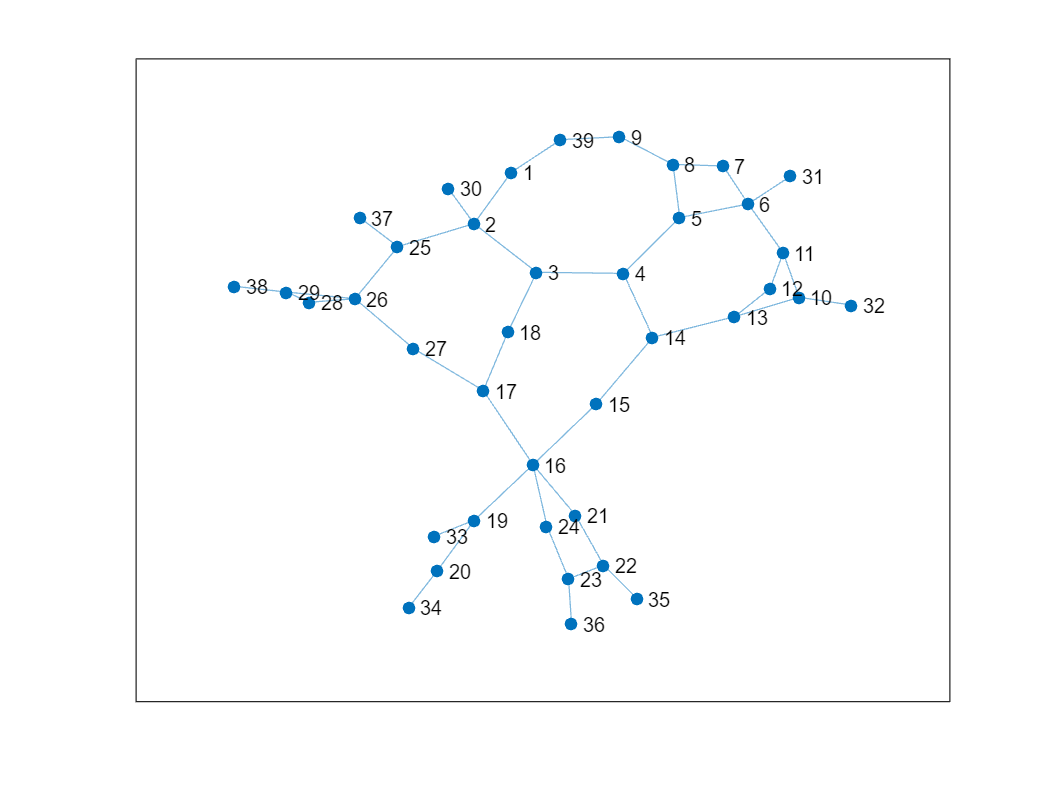

% % 画出网络拓扑图
fbus = mpc.branch(:,1);
tbus = mpc.branch(:,2);
figure
G = graph(fbus,tbus);
plot(G)

% % 节点16负荷有功增加200MW，节点39发电机有功减小200MW
mpc.bus(16,3) = mpc.bus(16,3) + 200;
mpc.gen(10,2) = mpc.gen(10,2) - 200;

% % 常规潮流-快速分解法
% % matpower8，如果是matpower7则不需要'exp.use_legacy_core'
mpopt = mpoption('pf.alg', 'FDXB','verbose',3,'exp.use_legacy_core',1);
mpopt.isD = 0;
runpf(mpc,mpopt)


MATPOWER Version 8.0b1, 22-Dec-2022 -- AC Power Flow (fast-decoupled, XB)

iteration     max mismatch (p.u.)  
type   #        P            Q     
---- ----  -----------  -----------
  -    0    1.942e+00    2.854e-05
  P    1    4.176e-01    5.612e-01
  Q    1    2.961e-01    1.105e-02
  P    2    7.315e-02    1.552e-01
  Q    2    4.113e-02    2.707e-03
  P    3    1.213e-02    2.702e-02
  Q    3    6.167e-03    5.259e-04
  P    4    2.151e-03    4.811e-03
  Q    4    1.068e-03    9.874e-05
  P    5    3.920e-04    8.773e-04
  Q    5    1.987e-04    1.835e-05
  P    6    7.212e-05    1.614e-04
  Q    6    3.683e-05    3.400e-06
  P    7    1.332e-05    2.980e-05
  Q    7    6.816e-06    6.293e-07
  P    8    2.462e-06    5.509e-06
  Q    8    1.261e-06    1.164e-07
  P    9    4.553e-07    1.019e-06
  Q    9    2.333e-07    2.154e-08
  P   10    8.422e-08    1.885e-07
  Q   10    4.317e-08    3.985e-09
  P   11    1.558e-08    3.487e-08
  Q   11    7.986e-09    7.373e-10
Fast-decoup

% % 动态潮流-快速分解法
% % matpower8，如果是matpower7则不需要'exp.use_legacy_core'
mpopt = mpoption('pf.alg', 'FDXB','verbose',3,'exp.use_legacy_core', 1);
mpopt.isD = 1;
runpf(mpc,mpopt)


MATPOWER Version 8.0b1, 22-Dec-2022 -- AC Power Flow (fast-decoupled, XB)

iteration     max mismatch (p.u.)  
type   #        P            Q     
---- ----  -----------  -----------
  -    0    1.937e+00    2.854e-05
  P    1    2.090e-01    2.774e-01
  Q    1    7.328e-02    5.299e-03
  P    2    1.747e-02    2.549e-02
  Q    2    6.081e-03    6.473e-04
  P    3    1.855e-03    2.691e-03
  Q    3    8.321e-04    8.529e-05
  P    4    1.812e-04    3.234e-04
  Q    4    1.124e-04    1.113e-05
  P    5    2.397e-05    4.298e-05
  Q    5    1.492e-05    1.435e-06
  P    6    3.157e-06    5.652e-06
  Q    6    1.975e-06    1.848e-07
  P    7    4.149e-07    7.414e-07
  Q    7    2.610e-07    2.383e-08
  P    8    5.441e-08    9.709e-08
  Q    8    3.437e-08    3.088e-09
  P    9    7.122e-09    1.270e-08
  Q    9    4.512e-09    4.007e-10
Fast-decoupled power flow converged in 9 P-iterations and 9 Q-iterations.

Converged in 0.02 seconds